# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**September 2, 2024**

# PART 1 - Problem 1

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [SYMBOLIC MATH TOOLBOX] [CONTROL TOOLBOX]`

The water level $y(t)$ in a tank is modelled by the differential equation


$$\frac{\mathrm{d}y(t)}{\mathrm{d}t} +y(t) = z(t)$$


where $z(t)$ denotes the inflow. The inflow is a function of a valve position, wich in turn is controlled by the control signal $u(t)$. The relation between the control signal $u(t)$ and the flow $z(t)$ is given by the differential equation:


$$\frac{\mathrm{d}^2 z(t)}{\mathrm{d}t^2} +\frac{\mathrm{d} z(t)}{\mathrm{d}t}+z(t) = u(t)$$


## Assignment

Your code shall solve the following problems:

- What differential equation relates the water level $y(t)$ to the control signal $u(t)$? Exploiting the **Laplace** **transform**, evaluate the transfer function from the control signal $u(t)$ [the input] to the water level $y(t)$ [the output]. **Save** the resulting expression in the **symbolic** **variable** `TF_uy`.

- **HINT**: Detailed help on how to use the `laplace()` function is available [here](https://it.mathworks.com/help/symbolic/sym.laplace.html).

- Create the `tf()` object `Gs`, corresponding to the symbolic expression `Tuy`.

- **HINT**: Detailed help on how to use the `tf()` function is available [here](https://it.mathworks.com/help/control/ref/tf.html?searchHighlight=tf&s_tid=srchtitle_support_results_1_tf).

- Properly using the command `lsim()`, calculate the output evolution correspondig to the input $u(t) = [2+sin(2t)]\cdot \mathbf{1}(t)$, where $\mathbf{1}(t)$ is, as usual, the unit step function.  For using in the command `lsim()`, generate an array of time instants $t_k \in [0\,,\;20]\;\text{s}$, with $t_k = k \cdot T\,,\; k = 0,\,1,\,\ldots\;,\quad T = 0.01\,\text{s}$. **Save** the resulting output evolution in the **numerical** **array** `Yt`.

- **HINT**: Detailed help on how to use the `lsim()` command is available [here](https://it.mathworks.com/help/control/ref/dynamicsystem.lsim.html?searchHighlight=lsim&s_tid=srchtitle_support_results_1_lsim).

- **Determine** the **state-space realisation in Observation Form** of the dynamical system `Gs`. 

- **Save** the resulting matrices in the **numerical** **matrices** `matA`, `matB`, `matC`, and `matD`.

- **HINT**: for the topic "*state-space realisation *" refer to Part 4 of the course material.

## Solution

### Init

clear
close all
clc


### From the ODEs to the Transfer Function

syms t s y(t) z(t) u(t)
syms Ys Zs Us
syms y0 z0 dotz0

y0 =  sym(0);
z0 = sym(0);
dotz0 = sym(0);

ODE_yz = diff(y(t), 1, t)+y(t) == z(t);
ODE_zu = diff(z(t), 2, t)+diff(z(t), 1, t)+z(t) == u(t);

L_yz = laplace(ODE_yz);
L_yz = subs(L_yz, [laplace(y(t),t,s), laplace(z(t),t,s), y(0)], [Ys, Zs, y0])

$$L\_yz = \mathrm{Ys}+\mathrm{Ys}\,s=\mathrm{Zs}$$

TF_yz = solve(L_yz,Ys)/Zs

$$TF\_yz = \frac{1}{s+1}$$

L_zu = laplace(ODE_zu);
L_zu = subs(L_zu, [laplace(u(t),t,s), laplace(z(t),t,s)], [Us, Zs])

$$L\_zu = \mathrm{Zs}-z\left(0\right)+\mathrm{Zs}\,s-s\,z\left(0\right)-\left({\left(\frac{\partial }{\partial t}z\left(t\right)\right)|}_{t=0}\right)+\mathrm{Zs}\,s^{2}=\mathrm{Us}$$

L_zu = subs(L_zu, [z(0), subs(diff(z(t), t), t, 0)], [z0, dotz0])

$$L\_zu = \mathrm{Zs}\,s^{2}+\mathrm{Zs}\,s+\mathrm{Zs}=\mathrm{Us}$$

TF_zu = solve(L_zu,Zs)/Us

$$TF\_zu = \frac{1}{s^{2}+s+1}$$

TF_uy = TF_zu*TF_yz

$$TF\_uy = \frac{1}{\left(s+1\right)\,\left(s^{2}+s+1\right)}$$

### The Transfer Function and the Output Movement

Gs = tf(1,[1 1])*tf(1,[1 1 1])


Gs =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


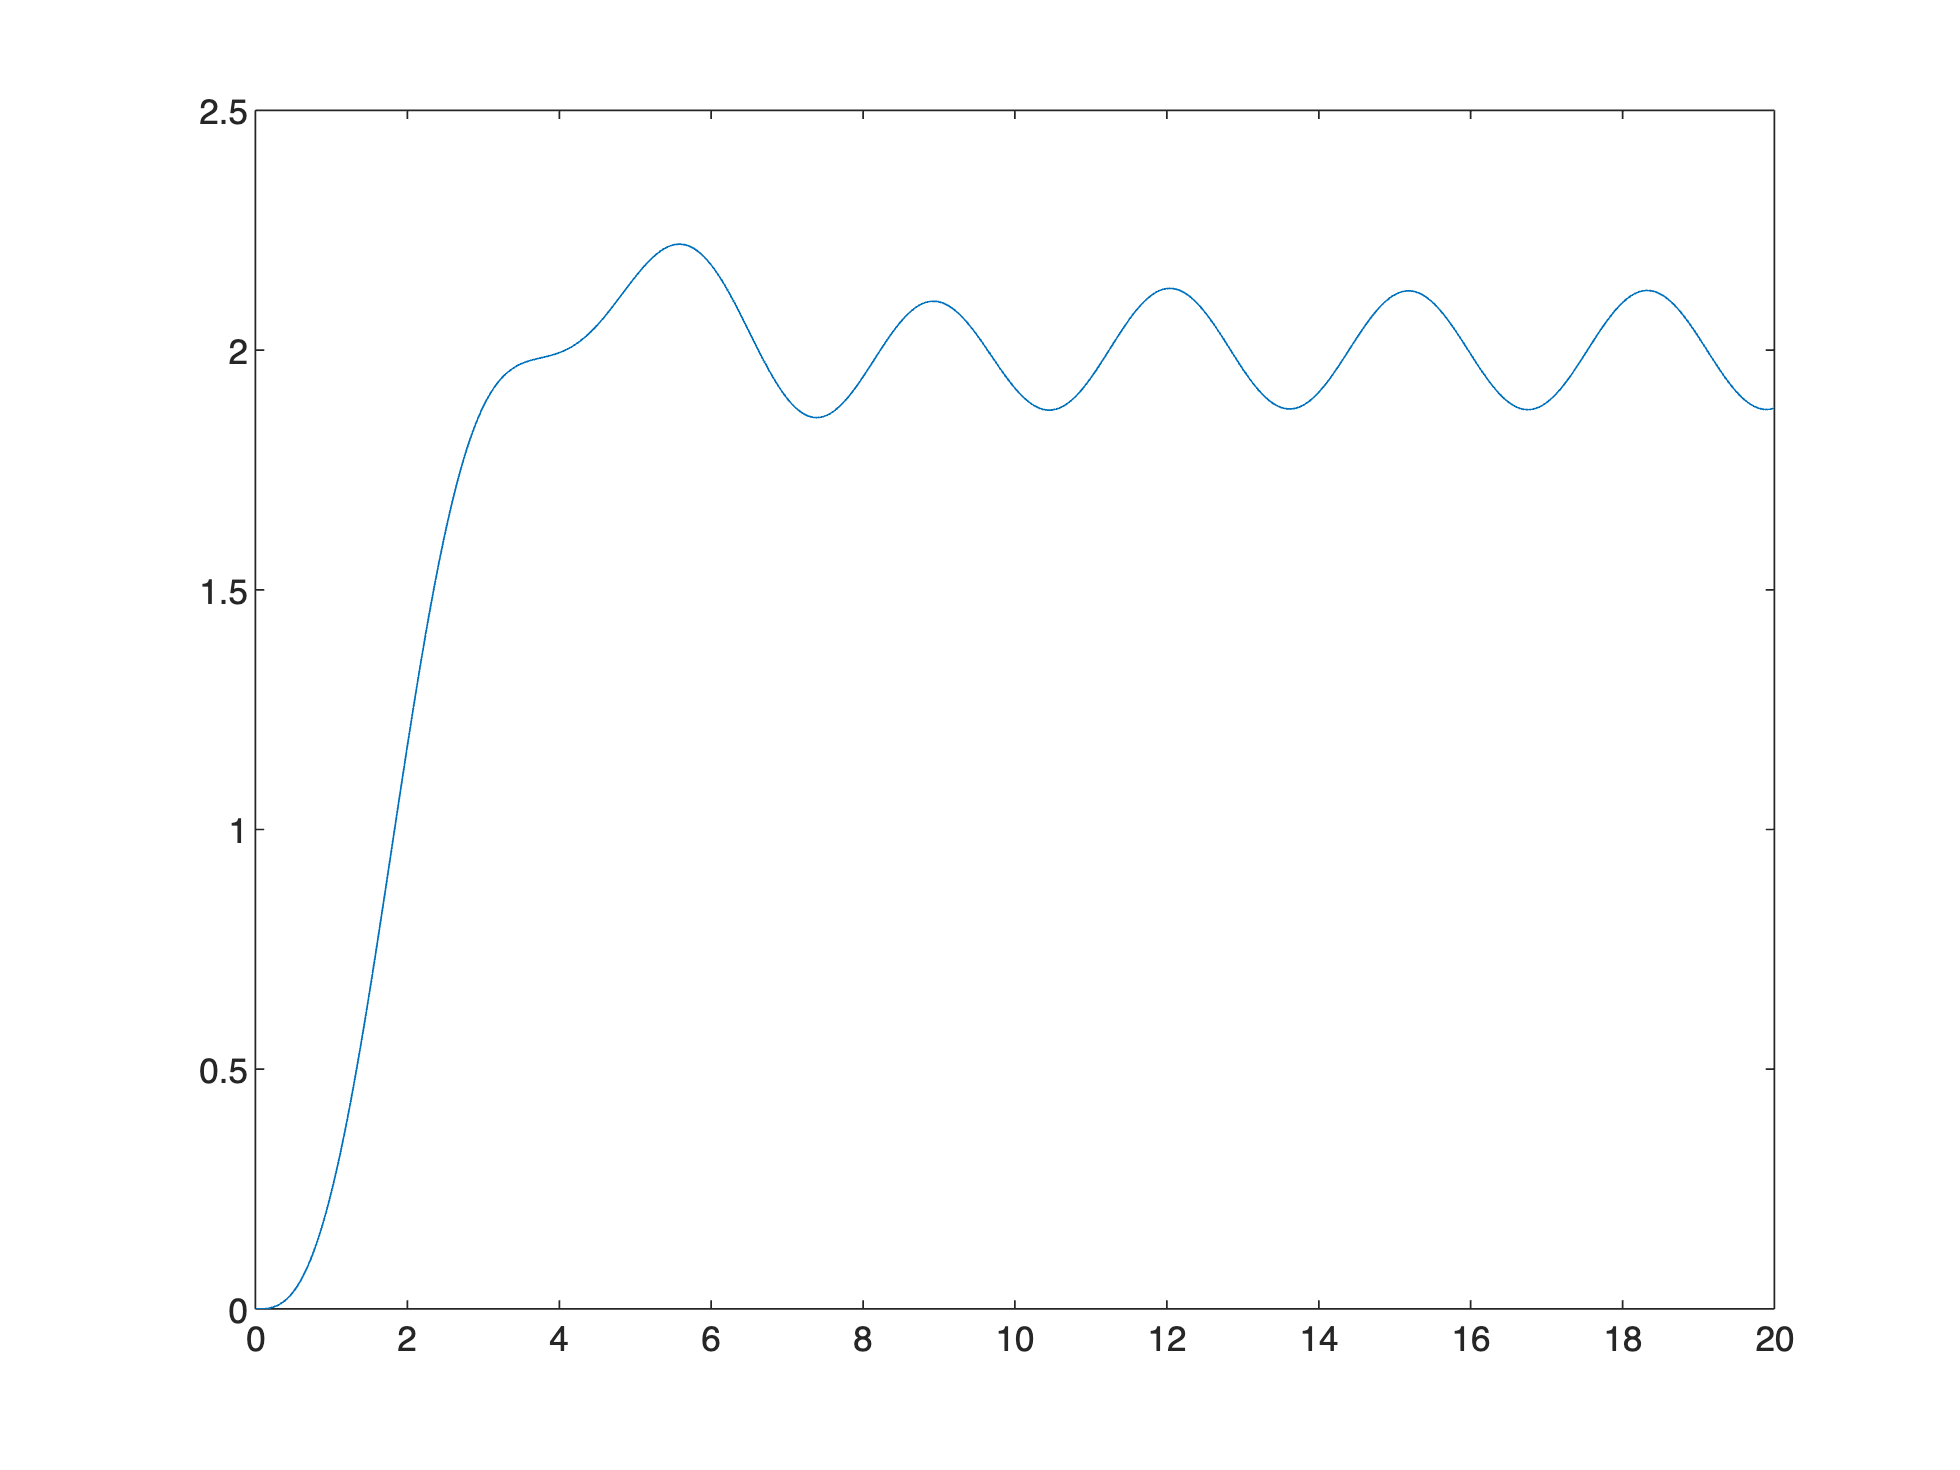

Tinit = 0; Tend = 20;
DeltaT = 0.01;
Tvect = (Tinit:DeltaT:Tend);
Uvect = 2+sin(2*Tvect);
Yt = lsim(Gs, Uvect, Tvect);

figure;plot(Tvect, Yt) % NON richiesto!!

### The State-Space Realisation

% the arrays with the numerator & denominator coefficients
[NsTFcoeffs, DsTFcoeffs] = tfdata(Gs, 'v') 

NsTFcoeffs =      0     0     0     1


DsTFcoeffs =      1     2     2     1


n = numel(pole(Gs)); % how many state variables? <--> the degree of denominator of G(s)
m = numel(zero(Gs)); % the degree of N(s) 
NsTFcoeffs = NsTFcoeffs(end-m:end);

% check
assert(n==(numel(DsTFcoeffs)-1))
assert(m==(numel(NsTFcoeffs)-1))

B2mat = sym([NsTFcoeffs; zeros(n-m-1, 1)]);           % the B matrix

C2mat = sym([zeros(1, n-1), 1]); % the C matrix

lastCol_A2 = transpose(DsTFcoeffs(1:end-1));
A2mat = sym([[zeros(1, n-1); eye(n-1)], ...
                 -lastCol_A2]) ;         % the A matrix

matA = double(A2mat);
matB = double(B2mat);
matC = double(C2mat);
matD = 0; % <-- SISO stricly proper system!

% last check
LTIsys = ss(matA, matB, matC, matD)


LTIsys =
 
  A = 
       x1  x2  x3
   x1   0   0  -1
   x2   1   0  -2
   x3   0   1  -2
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% NON richiesto
LTIsys_TF = tf(LTIsys)


LTIsys_TF =
 
            1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


% NON richiesto
% check equivalence -- is L_inf norm of difference (error) close enough to zero?  
tol = 1e-10; 
assert( norm( LTIsys_TF - Gs , 'inf' ) < tol , "G is not correct.")